# Calculo Cinematica Inversa

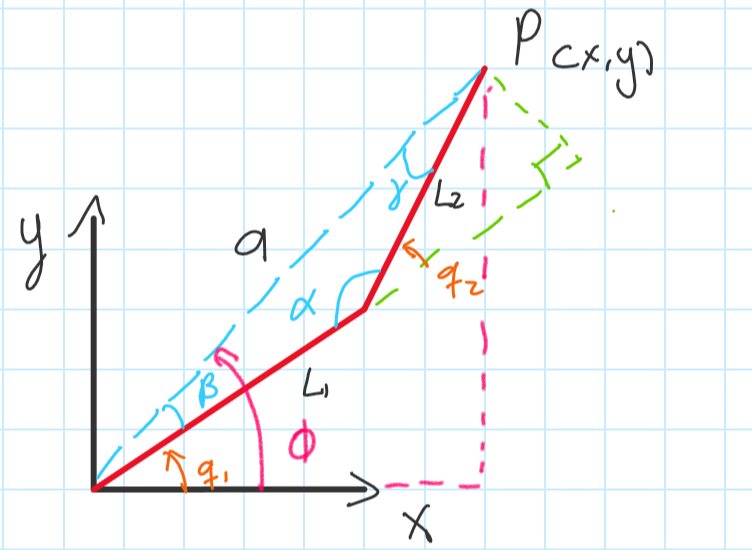

Se tiene el siguiente escenario para la cinematica inversa, dado un punto x,y en el espacio queremos conocer los valores angulares q1,q2 en el tiempo. 

Comenzamos definiendo los siguientes ángulos:


$$q_1 +\beta =\phi \Rightarrow q_1 =\phi -\beta$$



$$q_2 +\alpha =180\Rightarrow q_2 =180-\alpha$$


Podemos conocer a $\beta$ vemos que el cateto opuesto del triangulo que contiene a beta es el mismo que el cateto opuesto que contiene a $q_2$ , por tanto podemos utilzar $q_2$ como parte de nuestra relación$\begin{array}{l}
\tan =\frac{y}{x}\\
\tan \beta =\frac{L_2 \sin \left(q_2 \right)\;}{L_1 +L_2 \cos \left(q_2 \right)}
\end{array}$

Como ya conocemos la relación de beta podemos intentar resolver q1, q1 está en terminos de q2, por tanto cuando resolvamos para q2, q2 tiene que ser que ser independiente en sus valores.


$$q_1 =\phi -\beta$$


Sabemos de la ley de los cosenos que:

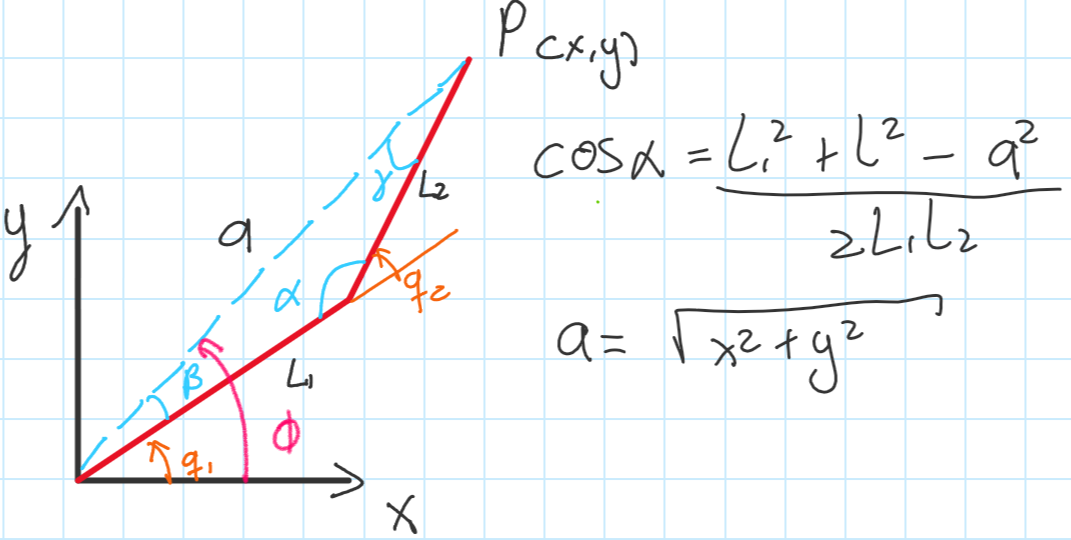


$$\cos \left(\alpha \right)=\frac{b^2 +c^2 -a^2 }{2\mathrm{bc}}=\frac{L_2^2 +L_1^2 -\left(x^2 +y^2 \right)\;}{2L_1 L_2 }$$
 

para $q_2$ tenemos por tanto:


$$\begin{array}{l}
q_2 =180-\alpha \\
\cos \left(q_2 \right)=\cos \left(180-\alpha \right)\Rightarrow \cos \left(q_2 \right)=-\cos \left(\alpha \right)\\
\cos \left(q_2 \right)=\frac{x^2 +y^2 -L_1^2 -L_2^2 }{2L_1 L_2 }\\
D=\frac{x^2 +y^2 -L_1^2 -L_2^2 }{2L_1 L_2 }
\end{array}$$


Sabemos que:


$${\mathrm{sen}\left(q_2 \right)}^2 +{\cos \left(q_2 \right)}^2 =1$$


por tanto:


$$\mathrm{sen}\left(q_2 \right)=\pm \sqrt{1-{\cos \left(q_2 \right)}^2 }=\sqrt{1-D^2 }$$


y obtenemos la tangente


$$\frac{\mathrm{sen}\left(q_2 \right)}{\cos \left(q_2 \right)}=\tan \left(q_2 \right)=\frac{\;\pm \sqrt{1-D^2 }}{D}$$


finalmente podemos despejar q2 por medio de atan2


$$q_2 =\mathrm{atan2}\left(\pm \sqrt{1-D^2 },D\right)$$


En resumen, nuestra cinematica inversa está dada por las siguientes ecuaciones:


$$\begin{array}{l}
D=\frac{x^2 +y^2 -L_1^2 -L_2^2 }{2L_1 L_2 }\\
q_{2\;} =\;\mathrm{atan2}\left(\pm \sqrt{1-D^2 },D\right)\\
q_1 =\mathrm{atan2}\left(y,x\right)-\mathrm{atan2}\left(L_2 \mathrm{sen}\left(q_2 \right),L_1 \cos \left(q_2 \right)\right)
\end{array}$$


Para comprobar esta solución, propondremos unos valores q_1 y q_2 arbitrarios, obtendremos nuestra posición x,y de nuestro robot por medio de la curva estilizada, y luego realizaremos la cinematica inversa a partir de dichos valores x,y y comprobar que se tengan los mismos valores q_1 y q_2 que se propusieron al comienzo.

%Longitud de los eslabones
L1 = 23;
L2 = 19;
%Valores cinematicos directos para un theta de pi/6
res = 10000;
theta = pi/4;
gamma = 0;
rho = (5+2*cos(3*(theta-gamma)))/7;
[x y] = pol2cart(theta,rho);
x = (x+2)*10

x = 23.6222

y = (y+2)*10

y = 23.6222

%Obtenemos la constante D una vez con los valores x,y
D = (x^2+y^2-L1^2-L2^2)/(2*L1*L2)

D = 0.2586

%Calculamos q2, como será codo arriba se toma la parte positiva de la raíz
q2 = atan2(sqrt(1-D^2),D)

q2 = 1.3092

q1 = atan2(y,x)-atan2(L2*sin(q2),L1+L2*cos(q2))

q1 = 0.2038

%Robot de 2 grados de libertad
%theta d a alpha
L(1) = Link([0 0 0 0],'modified');
L(2) = Link([0 0 L1 0],'modified');
R = SerialLink(L,'name','2GL','base',troty(-90,'deg'))

 
R = 
 
2GL (2 axis, RR, modDH, fastRNE)                                 
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|          0|         23|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 0  0 -1  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         1  0  0  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


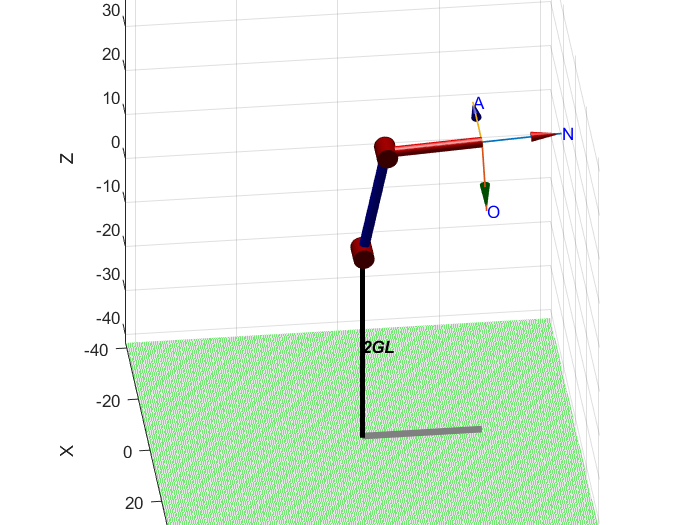

%% Considerando el tool
R_tool = [[1 0 0]' [0 1 0]' [0 0 1]']; % Orientacion de la tool
Ptool = [L2 0 0 1]';
R.tool = [[R_tool;[0 0 0]],Ptool]; 
figure;
R.plot([q1 q2],'noa')

view([83.4 30.3])

res = 1000;
theta = linspace(2*pi/res,2*pi,res);
gamma = 0;
rho = (5+2*cos(3*(theta-gamma)))/7;
[x_pos y_pos] = pol2cart(theta,rho);


q1 = 0;
q2 = 0;
for pos = 1:length(x_pos)
    
    x = x_pos(pos);
    x = (x+2)*10;
    y = y_pos(pos);
    y = (y+2)*10;
    [q1_temp q2_temp] = inversa2GDL(real(x),real(y),L1,L2,1);
    q1 = [q1 q1_temp];
    q2 = [q2 q2_temp];
    
end
anim = Animate('movie');

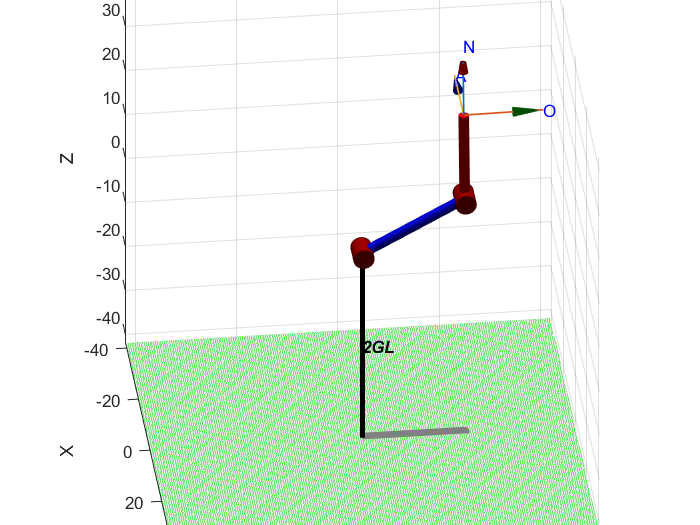

Unable to resolve the name shuttleVideo.FrameRate.

for i = 1:length(q1)
    R.plot([q1(i) q2(i)],'noa');
    anim.add();
    
end

function [q1,q2] = inversa2GDL(x,y,L1,L2,codo)
%INVERSA2GDL Summary of this function goes here
%   Detailed explanation goes here
D = (x^2+y^2-L1^2-L2^2)/(2*L1*L2);
if codo ==0
    q2 = atan2(+sqrt(1-D^2),D);
else
    q2 = atan2(-sqrt(1-D^2),D);
end
q1 = atan2(y,x)-atan2(L2*sin(q2),L1+L2*cos(q2));
end


